# data assignment

Age distribution between control and Intervetion 

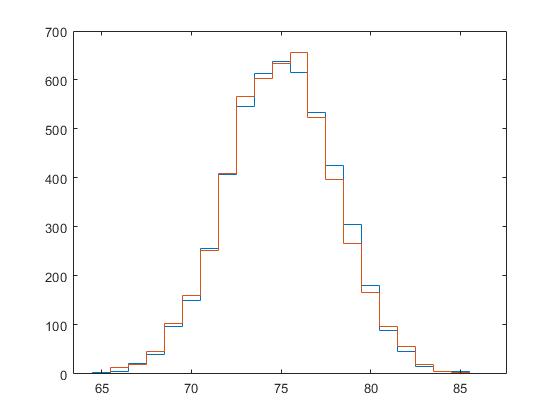

figure
histogram(tab.age(tab.group=='control'),'DisplayStyle',"stairs")
hold on
histogram(tab.age(tab.group=='intervention'),'DisplayStyle',"stairs")

## calculate stats

Gender distribution between control and Intervention

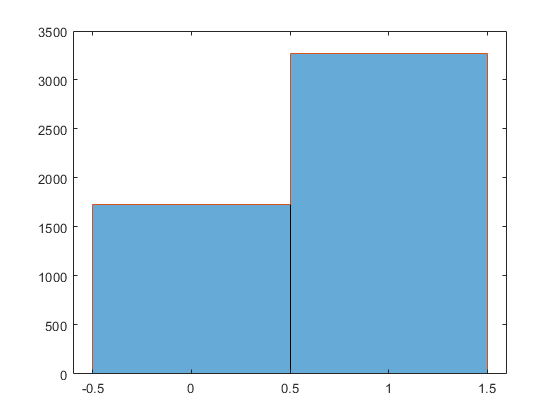

figure
hs(1)=histogram(tab.gender(tab.group=="control"),'DisplayStyle',"bar"); %% i want to present bar
hold on
hs(2)=histogram(tab.gender(tab.group=="intervention"),'DisplayStyle',"stairs");

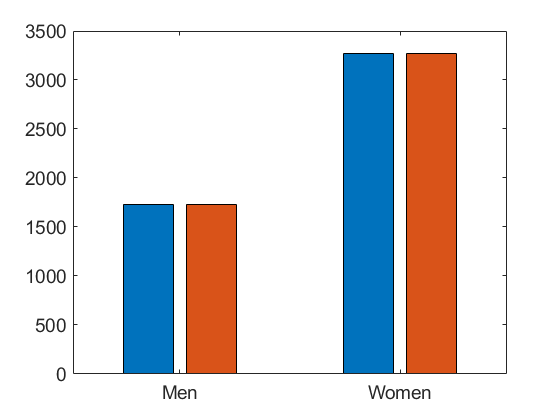

figure;
bar([0  1],[hs(1).Values ;hs(2).Values]')
set(gca,'XTickLabel',{'Men','Women'},'fontsize',14)

state distrubution

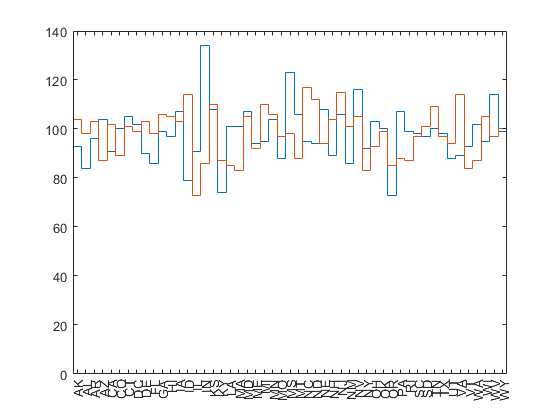

figure
hs(1)=histogram(tab.state(tab.group=="control"),'DisplayStyle',"stairs");
hold on
hs(2)=histogram(tab.state(tab.group=="intervention"),'DisplayStyle',"stairs");

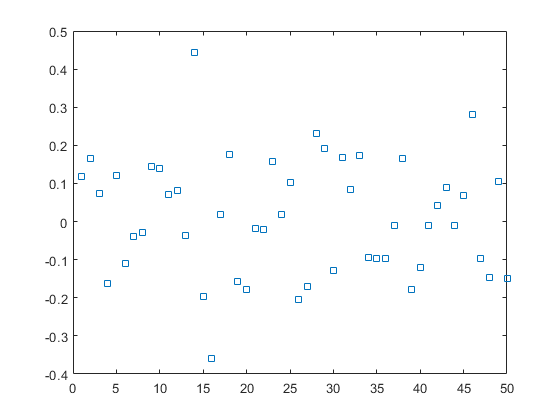


figure
plot(hs(2).Values./hs(1).Values-1,'s')
xlim([0 50])

who is more prone to detirurate

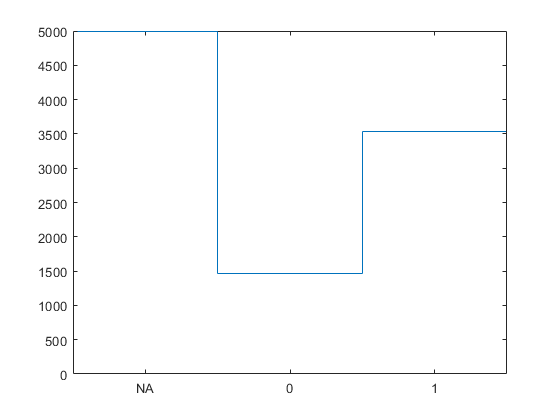






figure
histogram(tab.questionnairecomplete,'DisplayStyle',"stairs")

% hold on
msk0=tab.group=="intervention" & tab.questionnairecomplete=="0";
msk1=tab.group=="intervention" & tab.questionnairecomplete=="1";



fprintf('Percentage of intervention group with filled questionaire: %f',sum(msk1)./sum(tab.group=="intervention").*100)

Percentage of intervention group with filled questionaire: 70.660000

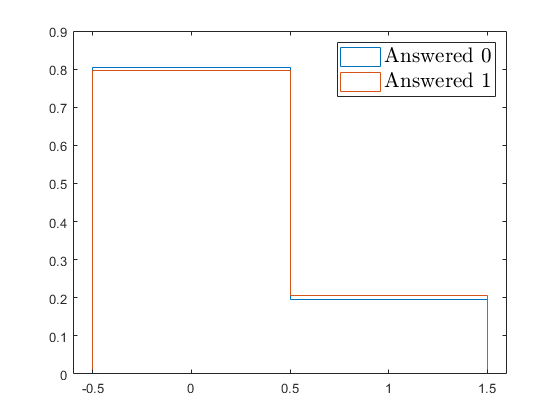



hs(1)=histogram(tab.ltcb(msk0),'DisplayStyle',"stairs",'DisplayName','Answered 0',...
    'Normalization',"probability");
hold on
hs(2)=histogram(tab.ltcb(msk1),'DisplayStyle',"stairs",'DisplayName','Answered 1',...
    'Normalization',"probability");
legend(hs,'interpreter','latex','FontSize',16,'location','northeast')







%plot(tab.ltcb(tab.group=="control"),tab.ltcb(tab.group=="intervention"),'o')


## bin by ages

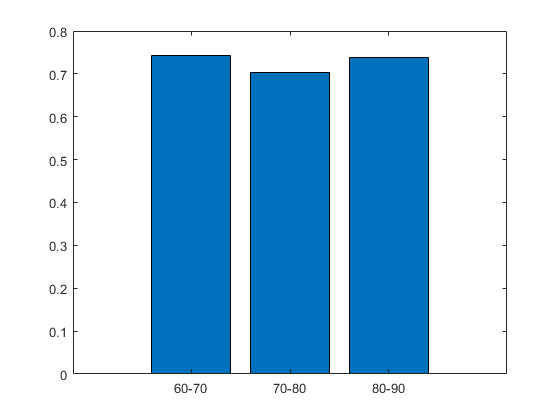

ageBins=60:10:90;
binInd=discretize(tab.age,ageBins);

ageAnswer=zeros(1,length(ageBins)-1);
for i=1:length(ageBins)-1
    ageAnswer(i)=sum(tab.questionnairecomplete(binInd==i)=="1")./sum(tab.group(binInd==i)=="intervention");
    
end

figure
bar(1:length(ageBins)-1,ageAnswer)
set(gca,'XTickLabel',{'60-70','70-80',' 80-90'})

who answers qustioniree more men or women?

% figure
% histogram(tab.questionnairecomplete,"1")

which states are more complient?

what is the detiriration rate in the compliant group in comparison to the non-complaint group and to the control?